# **Lab 4 - Triangulation**

## **Using Ransac**

This whole lab is basically concerned with the camera equation


$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\lambda u=P\;U$$


For the uncalibrated case, $u$ is a 3-vector with the coordinates of a point in the image (and an added 1)


$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;u=\left\lbrack \begin{array}{c}
x\\
y\\
1
\end{array}\right\rbrack$$


and $U$ is a 4-vector containing the coordinates of the corresponding 3D point along with a 1 in its last element. A function

    `[Ps, us, U_true] = triangulation_test_case(sigma)`

is provided for creating a simple test case where you know the correct answer (`U_true`). Gaussian noise of standard deviation `sigma` is added to the image points. Use this example to evaluate the your minimal solver.

**Ex 4.1**     Make a minimal solver for the triangulation problem, that is, a function 

    `U = minimal_triangulation(Ps, us)`

that takes two camera matrices, `Ps`, and two image points, `us`, and triangulates a 3D point. The image points are a 2 x 2 array whereas the camera matrices is a cell list with one camera matrix in each cell. 

sigma = 0.1;

[Ps, us, U_true] = triangulation_test_case(sigma)

Ps = 1×2 cell array
    {3×4 double}    {3×4 double}


us =  -457.2674 -424.5805
 -489.0492 -339.3451


U_true =     0.0975
    0.2785
    0.5469



U = minimal_triangulation(Ps, us)

U =     0.0864
    0.2699
    0.6043


Recall that $\lambda$ is the *depth*. Points with negative depth would lie behind the camera, so negative depths indicate that something is wrong.

**Ex 4.2**     Make a function 

`    positive = check_depths(Ps, U)`

that takes *N* camera matrices, `Ps`, and a single 3D point, `U`, and checks the depth of `U` in each of the cameras. The output should be a an array of boolean values of length *N* that indicates which depths were positive. (Matlab will print boolean values as zeros and ones, so don’t be confused by this.)

positive = check_depths(Ps, U)

positive = 2×1 logical array
   1
   1


**Ex 4.3**     Make a function 

    `errors = reprojection_errors(Ps, us, U)`

that takes *N* camera matrices, `Ps`, *N* image points, `us`, and a single 3D point, `U`, and computes a vector with the reprojection errors, that is, the lengths of the reprojection residuals. If a point has negative depth, set the reprojection error to `Inf`. 

errors = reprojection_errors(Ps, us, U)

errors =     0.0000
    0.6353


**Ex 4.4**     Make a function 

`    [U, nbr_inliers] = ransac_triangulation(Ps, us, threshold) `

that implements triangulation using Ransac. Use the number of outliers as loss function. A measurement is deemed as an outlier if the depth is negative or if the reprojection error is larger than `threshold`. 

threshold = 0.1;
[U, nbr_inliers] = ransac_triangulation(Ps, us, threshold)

U =     0.0864
    0.2699
    0.6043


nbr_inliers = 1

In `sequence.mat` you find a struct array `triangulation_examples` with triangulation examples. Each example (3D point) has a cell list of camera matrices `Ps` and a 2 x N-array `us` with image points. It will take some time to triangulate all 32183 examples so start with the first 1000 or so. We used a Ransac threshold of 5 pixels. 

**Ex 4.5**     Make a script `triangulate_sequence` that runs `ransac_triangulation` for all (or at least 1000) of the examples from `sequence.mat`. Store all triangulated points with at least two inliers and plot them using `scatter3`. There will always be a few outliers among the estimated 3D points that make it harder to view the plot. You can use the provided `clean_for_plot.m` to clean it up a bit. 

triangulate_sequence   % Script that you need to create

% Us: 3xN matrix with triangulated 3D points, should be created inside the
% script 'triangulate_sequence'

Uc = clean_for_plot(Us) 

Uc =   -17.4556  -18.1860  -15.7877  -14.1041  -16.7118  -16.5058  -14.9013  -17.9679  -17.2068  -16.6272  -14.5166  -12.6170  -12.5834  -12.5533  -12.9735  -17.6760  -17.8062  -17.5344  -16.9404  -12.6518  -13.0168  -13.1008  -18.3483  -18.1453  -17.2406  -17.1248  -17.0505  -16.9458  -16.9316  -16.7467  -15.6544  -12.6263  -13.0654  -12.9979  -13.1230  -12.9257  -18.4071  -18.2645  -18.0158  -17.8755  -17.5386  -17.5885  -17.3939  -17.3721  -17.4001  -17.4048  -17.3103  -17.1679  -17.1526  -17.1297
    4.0475    4.9207    5.3764    5.7153    5.2349    5.2661    5.5227    5.2916    5.4823    5.4506    5.7457    2.0854    2.3469    2.3424    5.0580    5.2614    5.2835    5.4686    5.3508    3.1214    5.0540    6.1049    5.1644    5.1916    5.6120    5.6126    5.5757    5.6085    5.5858    5.2574    5.4899    3.3026    5.3560    5.3249    5.7312    5.8707    5.1303    5.2383    5.1840    5.5436    5.3795    5.3140    5.4459    5.5092    5.2599    5.2614    5.6983    5.5441    5.5496    

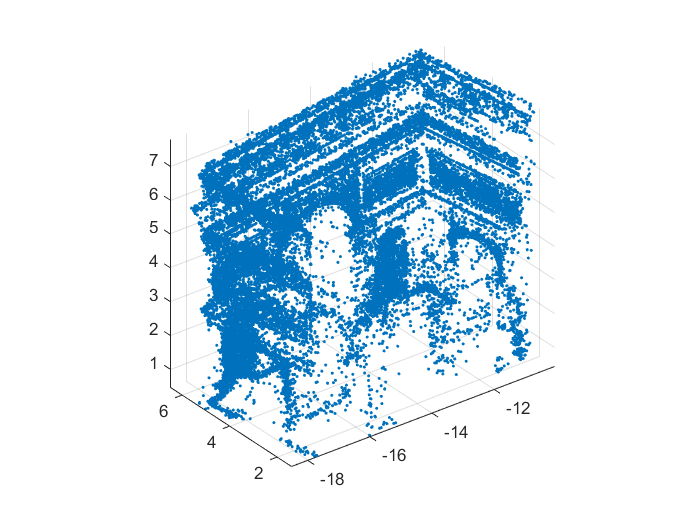

scatter3(Uc(1,:),Uc(2,:),Uc(3,:),'.') 
axis equal

Can you recognize the building? 

"Arc de Triomphe de l'Etoile"

ans = "Arc de Triomphe de l'Etoile"

## Least squares triangulation 

In this part of the lab you will solve the tringulation problem through least squares. Just as in the case of registration, the following pipeline is recommended: 

    - Use Ransac to obtain a rough estimate of the parameters (*U*). 

    - Remove all measurements which are outliers with respect to these parameters. 

    - Estimate the least squares parameters using the remaining measurements. 

Note that in this case a *measurement* is a pair consisting of an image point $u_i$ and a camera matrix $P_i$. Don’t forget that points with negative depths should be outliers. To test your functions you can use, for instance, some of the 3D points, camera matrices and image measurements from the provided data for the previous exercises. 

**Ex 4.6**     Consider a camera matrix 

                        $P_i =\left\lbrack \begin{array}{c}
\longleftarrow a_i^T \longrightarrow \\
\longleftarrow b_i^T \longrightarrow \\
\longleftarrow c_i^T \longrightarrow 
\end{array}\right\rbrack$ ,

a 3D point *U* and an image point $u_i$. Write the formula for the reprojection error $r_i \left(U\right)$ below. 

    $r_i \left(U\right)={\left(\frac{a_i^T \;U}{c_i^T \;U}\;\;\;\;\;\;\frac{b_i^T \;U}{c_i^T \;U}\;\right)}^T -u_i$           if   $c_i^T \;U>0$

  
$$r_i \left(U\right)=\left\lbrack \begin{array}{c}
\frac{a_{i,1} \;U_1 +a_{i,2} \;U_2 +a_{i,3} \;U_3 \;}{c_{i,1} \;U_1 +c_{i,2} \;U_2 +c_{i,3} \;U_3 }\\
\frac{b_{i,1} \;U_1 +b_{i,2} \;U_2 +b_{i,3} \;U_3 \;}{c_{i,1} \;U_1 +c_{i,2} \;U_2 +c_{i,3} \;U_3 }
\end{array}\right\rbrack -u_i$$


As you can see, the residuals are no longer linear, so computing a least squares solution will be significantly harder than in the previous lab. In fact, we cannot be sure to find the least squares solution. What we can do is to use local optimization to reduce the sum of squared residuals. We start at the solution produced by Ransac and use a few Gauss-Newton iterations.

**Ex 4.7**     Make a function 

`    all_residuals = compute_residuals(Ps, us, U)`

that takes a cell list `Ps` with *N* cameras, a 2 x *N* array `us` of image points and a 3 x 1 array `U`, and computes a 2*N* x 1 array with all the reprojection residuals stacked into a single vector/array. A reprojection residual is a 2D vector corresponding to the difference between the original measurement and the projected point. The stacked vector is the $\bar{r}$ from the lecture notes (page 99).

all_residuals = compute_residuals(Ps, us, U)

all_residuals =    -0.0000
    0.0000
    0.4962
    0.3966


**Ex 4.8**     Find formulas for the partial derivatives in the Jacobian of $\bar{r}$. The Jacobian should be a 2N x 3- matrix.  

    
$$\begin{array}{l}
J_i =\left\lbrack \begin{array}{ccc}
\frac{{\partial r}_{i,x} }{\partial U_1 } & \frac{{\partial r}_{i,x} }{\partial U_2 } & \frac{{\partial r}_{i,x} }{\partial U_3 }\\
\frac{{\partial r}_{i,y} }{\partial U_1 } & \frac{{\partial r}_{i,y} }{\partial U_2 } & \frac{{\partial r}_{i,y} }{\partial U_3 }
\end{array}\right\rbrack \\
\;\;\;=\left\lbrack \begin{array}{ccc}
\frac{a_{i,1} \;C_i -c_{i,1} \;A_i \;}{{C_i }^2 } & \frac{a_{i,2} \;C_i -c_{i,2} \;A_i \;}{{C_i }^2 } & \frac{a_{i,3} \;C_i -c_{i,3} \;A_i \;}{C^2 }\\
\frac{b_{i,1} \;C_i -c_{i,1} \;B_i \;}{{C_i }^2 } & \frac{b_{i,2} \;C-c_{i,2} \;B\;}{{C_i }^2 } & \frac{b_{i,3} \;C_i -c_{i,3} \;B_i \;}{{C_i }^2 }
\end{array}\right\rbrack 
\end{array}$$


with $\;\;\;\;\;A_i =a_{i,1} \;U_1 +a_{i,2} \;U_2 +a_{i,3} \;U_3 +a_{i,4}$ , 

           
$${B_i \;=\;b}_{i,1} \;U_1 +b_{i,2} \;U_2 +b_{i,3} \;U_3 +b_{i,4}$$


           
$$C_i =\;c_{i,1} \;U_1 +c_{i,2} \;U_2 +c_{i,3} \;U_3 +c_{i,4}$$


**Ex 4.9**     Make a function 

`    jacobian = compute_jacobian(Ps, U)`

 that computes the Jacobian given a 3 x 1- vector `U` and a cell array of camera matrices `Ps`. 

jacobian = compute_jacobian(Ps, U)

jacobian =   462.4289   15.5714   93.0202
   -4.7019  468.0671   72.2381
  485.2594   -0.3050  104.1137
    0.3562  485.7029   81.1225


**Ex 4.10**     Use these functions to make a function 

`    U = refine_triangulation(Ps, us, Uhat)`

that uses an approximate 3D point `Uhat` as a starting point for Gauss-Newton’s method. Use five GaussNewton iterations. Print the sum of squared residuals after each Gauss-Newton step to verify that it decreases. 

U = refine_triangulation(Ps, us, U)

U =     0.0981
    0.2790
    0.5451


**Ex 4.11**     Try your `refine_triangulation` on the data in `gauss_newton.ma`t. First plot the points given in `Uhat`, then refine each point using your function and plot the results using `scatter3`. You should see an improvement. 

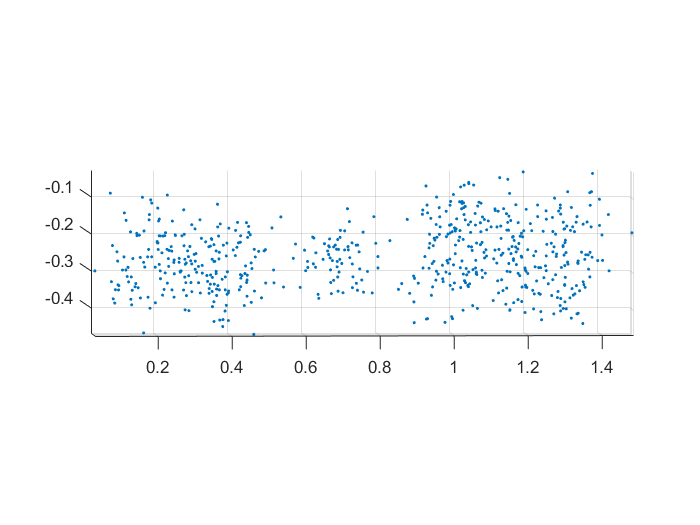

load('gauss_newton.mat')
scatter3(Uhat(1,:),Uhat(2,:),Uhat(3,:),'.') 
axis equal
view([-2.293 1.534])

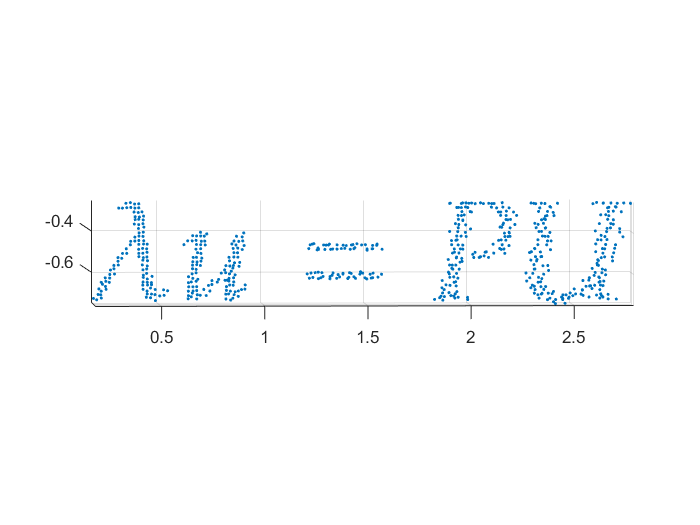

Ps{1} = P;
Ps{2} = P_tilde;

U = zeros(size(Uhat));
for i = 1:size(u,2)
    U(:,i) = refine_triangulation(Ps, [u(:, i) u_tilde(:, i)] , Uhat(:,i));
end
scatter3(U(1,:),U(2,:),U(3,:),'.') 
axis equal

view([-2.293 1.534])

**Ex* 4.12**     Compute the camera positions for the data in `gauss_newton.mat` and plot them together with the estimated 3D points. Try to understand why the noise in the estimated points looks as it does. 

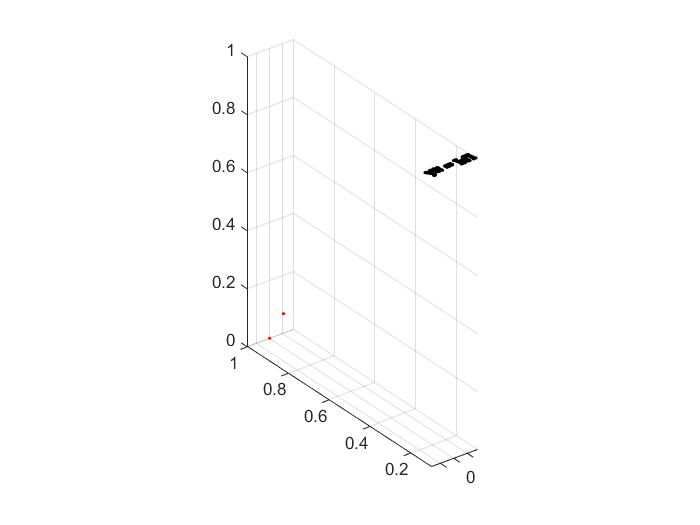

% YOUR CODE HERE; don't forget to plot your results

%scatter3(U(1,:)*1000,U(2,:)*1000,U(3,:)*1000,'b.') 

%C = [0, 0.049601937168260; 1, 0.996396396314305; 0, 0.068803119413454];

%scatter3(u_tilde(1,:)/300,u_tilde(2,:)/300,ones(1, size(u,2)),'k.') 
%hold on
%scatter3(C(1,:),C(2,:),C(3,:),'r.') 
%axis equal
%hold off

For the next exercise try the following way to match features, 

` matchFeatures(d1,d2,'Method','Approximate','MaxRatio',0.9,'MatchThreshold',100)`

The approximate option makes it go significantly faster. A Lowe ratio of 0.9 is very high, but it makes the model more *dens*e. 

**Ex* 4.13**     There are images `duomo.jpg` and `duomo_tilde.jpg` in the lab folder and also a data file `duomo.mat` with two camera matrices. Extract SIFT features from the two images (using `extractSIFT`) and match them using `matchFeatures`. Also store the color of each SIFT point. It doesn’t matter from which of the images you select the color information. 

Use your triangulation code (don’t forget r`efine_triangulation`) to triangulate the points and plot them with the right color using `scatter3`. Again, you can use `clean_for_plot.m` to remove outliers among the estimated 3D points. Beware that triangulating all the points will take a little time so work with a subset until you are sure that the code works. 

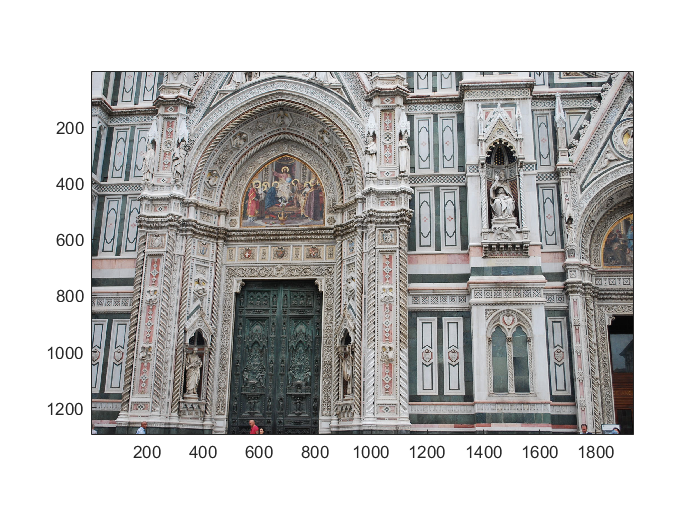

addpath('./sift');

duomo1 = imread('duomo.jpg'); 
imagesc(duomo1); axis image;

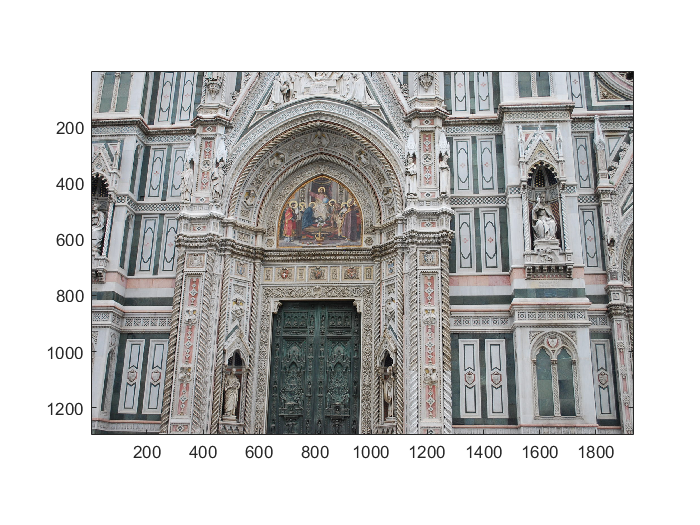

duomo2 = imread('duomo_tilde.jpg'); 
imagesc(duomo2); axis image;


load duomo.mat 
Ps{1} = P;
Ps{2} = P_tilde;

duomo1_bw = im2double(duomo1); % Convert to double
duomo1_bw = mean(duomo1_bw, 3);

duomo2_bw = im2double(duomo2); % Convert to double
duomo2_bw = mean(duomo2_bw, 3);

% Extract SIFT and match features
[pts1, descs1] = extractSIFT(duomo1_bw);
[pts2, descs2] = extractSIFT(duomo2_bw);
corrs = matchFeatures(descs1', descs2', 'MaxRatio', 0.9, 'MatchThreshold', 100);

threshold = 0.1;

colors = zeros(1, size(corrs,1));
U = zeros(3, size(corrs,1));
for i = 1:10
    colors(i) = duomo1_bw(pts1(:,corrs(i,1)));
    [Uhat, nbr_inliers] = ransac_triangulation(Ps, [pts1(:,corrs(i,1)) pts2(:,corrs(i,2))], threshold);
    U(:,i) = refine_triangulation(Ps, [pts1(:,corrs(i,1)) pts2(:,corrs(i,2))] , Uhat);
end

Array indices must be positive integers or logical values.

[Us_clean,removed_indices] = clean_for_plot(U)
colors(removed_indices)= [];




## **Essential Matrix**

**Ex 4.14**     Load the data in `P.mat`. There you will find two calibrated camera matrices, `P1` and `P2`. Make a function 

`    E = essentialMatrix(P1,P2)`

that computes the essential matrix `E` from `P1` and `P2` .

% TRY YOUR FUNCTION HERE


**Ex* 4.15**     Similar to the reprojection error in the triangulation problem, the essential matrix can also be used for outlier detection using the residual


$$r^2 =\frac{\left|{\tilde{x} }^T \;E\;x\;\right|}{{\left\|S\;E\;x\right\|}^2 +{\left\|S\;E^T \;\;\tilde{x} \right\|}^2 \;},\;\;\;\;\;\;\;\;\;\;S=\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 0
\end{array}\right\rbrack$$


where $x$ and $\tilde{x}$ are the image projections of a 3D point *X* using some arbitrary camera matrices $P$ and $\tilde{P}$, respectively. Note that $r$ does not depend on X. Assuming that you are using a similar threshold for outlier detection, for a set of pixel correspondences, you would get `I1` inliers if you use the residual from the triangulation problem and `I2` inliers if you used the residual from (4.4). Which one is greater, `I1` or `I2`? Why? 

""

ans = ""

**Submit this live script with all the plots visible. The functions will be tested automatically so make sure they all have the names, inputs and outputs as described in the lab PM. **